# Orientation Distribution Functions $\psi(\mathbf{p})
$

The Jeffery distribution is exact when every fiber follows Jeffery's equation, and is a good approximation for the orientation distribution function for other cases, such as when rotary diffusion is present.  This distribution is


$$\psi(\mathbf{p}) = \frac{1}{4 \pi \left( \mathbf{p} \cdot \mathbf{B}^{-1} \cdot \mathbf{p} \right)^{-3/2}}$$


where $\mathbf{B}^{-1}$ is the Piola tensor, related to the deformation gradient tensor $\mathbf{F}$ by


$$\mathbf{B}^{-1} = \mathbf{F}^{-T} \cdot \mathbf{F}^{-1}$$


The function `A2F` in Fiber Orientation Tools finds the $\mathbf{F}$ tensor for any second-order orientation tensor $\mathbf{A}$.   

## Uniaxial Orientation

Here is the first example from Figure 2.5.

fprintf('Orientation tensor, uniaxial orientation in the 1 direction\n')

Orientation tensor, uniaxial orientation in the 1 direction


A = diag([0.6, 0.2, 0.2])

A =     0.6000         0         0
         0    0.2000         0
         0         0    0.2000


fprintf('Corresponding F tensor from A2F\n')

Corresponding F tensor from A2F


F = A2F(A)

F =     1.8980         0         0
         0    0.7259         0
         0         0    0.7258


We'll use a utility function `drawPsi` to plot the distribution function.  This generates a grid of points on the surface of a sphere, calculates $\psi(\mathbf{p})$ at each point using the Jeffery distribution, and draws the function using the Matlab `surf` command.  Look into `drawPsi.m` to see the details of calculation $\psi(\mathbf{p})$.  

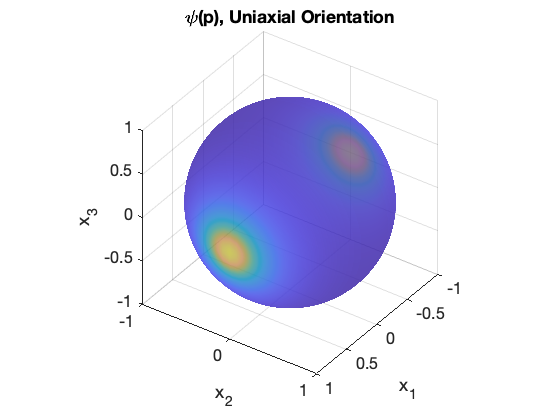

hs = drawPsi(F);
set(hs, 'FaceAlpha', 0.6)  % Make the sphere slightly transparent
view(125, 35)
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
title('\psi(p), Uniaxial Orientation')
set(gca, 'FontSize', 16)

## Biaxial Orientation

The second example is for nearly biaxial orientation in the 1-2 plane

fprintf('Orientation tensor, biaxial orientation in the 1-2 plane\n')

Orientation tensor, biaxial orientation in the 1-2 plane


A = diag([0.45, 0.45, 0.1])

A =     0.4500         0         0
         0    0.4500         0
         0         0    0.1000


fprintf('Corresponding F tensor from A2F\n')

Corresponding F tensor from A2F


F = A2F(A)

F =     1.4752         0         0
         0    1.4752         0
         0         0    0.4595


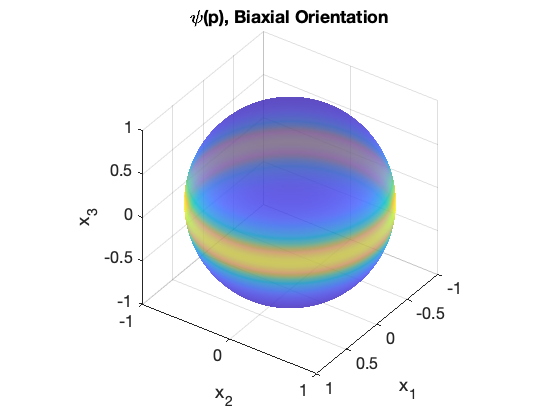

hs = drawPsi(F);
set(hs, 'FaceAlpha', 0.6)  % Make the sphere slightly transparent
view(125, 35)
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
title('\psi(p), Biaxial Orientation')
set(gca, 'FontSize', 16)

## Typical Injection Molding Shell Orientation

The third example is more typical of the shell orientation for injection molding.  The orientation tensor in this example is chosen to have an orientation peak that is clearly not on the 1 coordinate axis, with different degrees of spread in the 2 and 3 directions.

fprintf('Orientation tensor, typical shell orientation\n')

Orientation tensor, typical shell orientation


A = [0.6, 0, 0.10; 0, 0.3, 0; 0.10, 0, 0.1]

A =     0.6000         0    0.1000
         0    0.3000         0
    0.1000         0    0.1000


fprintf('Corresponding F tensor from A2F\n')

Corresponding F tensor from A2F


F = A2F(A)

F =     2.1127   -0.0000    0.3263
   -0.0000    1.0987   -0.0000
    0.3263   -0.0000    0.4812


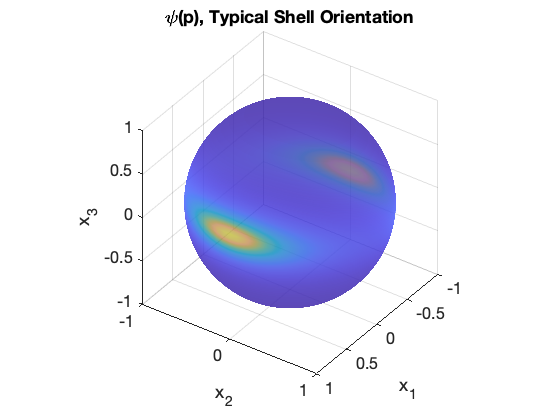

hs = drawPsi(F);
set(hs, 'FaceAlpha', 0.6)  % Make the sphere slightly transparent
view(125, 35)
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
title('\psi(p), Typical Shell Orientation')
set(gca, 'FontSize', 16)